# Trabajo grupal 1 (Métodos Numéricos)

- Sección:

- N° de grupo: 

- Integrante 1 (líder):         

- Integrante 2:

- Integrante 3:

- Integrante 4:

- Integrante 5:

**Observación:** No olvidar añadir el porcentaje de participación.

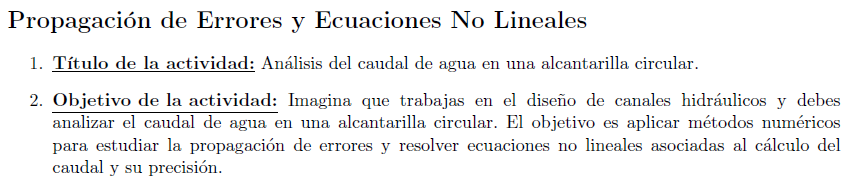

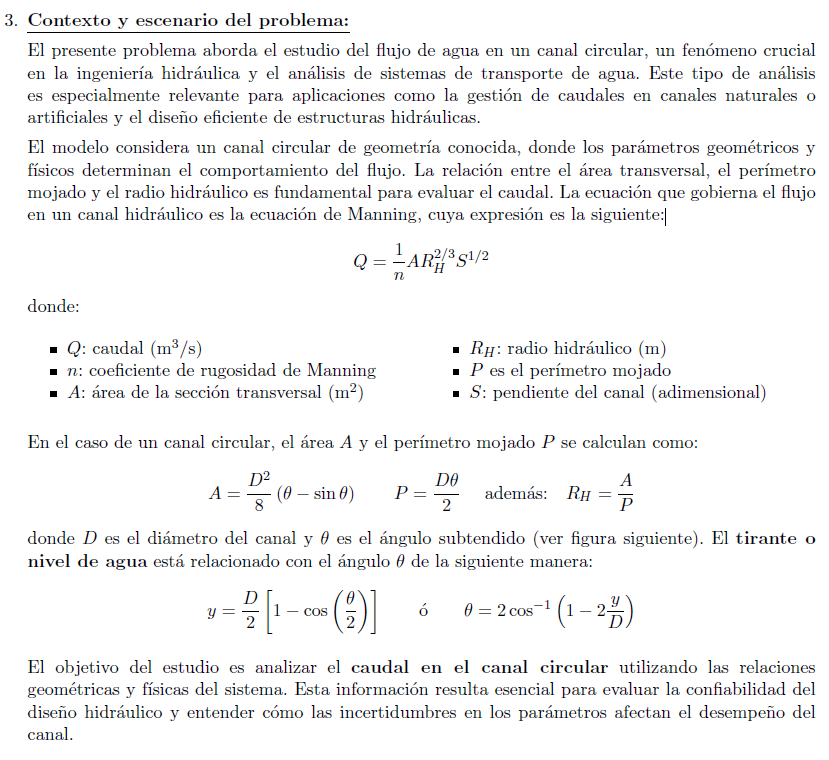

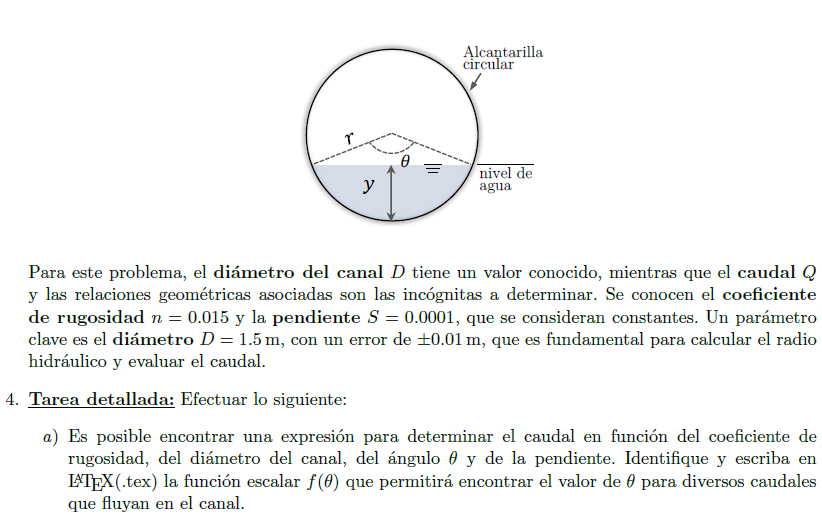

% escriba su función usando Latex


$$f(\theta) = \frac{1}{n} \left( \frac{D^2}{8} (\theta - \sin \theta) \right) \left( \frac{D}{4 {\theta}} (\theta - \sin \theta) \right)^{2/3} S^{1/2} - Q$$


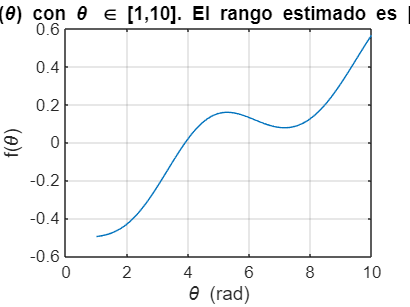

% realice el gráfico y estime el intervalo pedido

n = 0.015;
D = 1.5;
S = 0.0001;
Q = 0.5;

f = @(theta) ((1 / n) * ((D^2 / 8) * (theta - sin(theta))) .* ...
    ((D ./ (4 * theta)) .* (theta - sin(theta))).^(2/3) * (S)^(1/2) - Q);

theta = linspace(1, 10, 1000);
f_values = f(theta);

plot(theta, f_values);
xlabel('\theta (rad)');
ylabel('f(\theta)');
title('f(\theta) con \theta \in [1,10]. El rango estimado es [3,4]');
grid on;

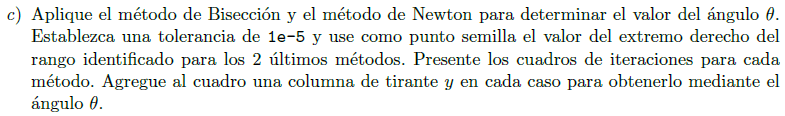

% presente aquí su resolución y los cuadros pedidos

a = 3; b = 4;
tol = 1e-5;

tirante = @(theta) (D/2) .* (1 - cos(theta./2));

m1 = biseccion2(f, a, b, tol);
m1 = [m1 tirante(m1(:,2))] % respuesta del metodo de biseccion, a c b f(a) f(c) f(b) error tirante

m1 =    3.000000000000000   3.500000000000000   4.000000000000000  -0.230059639968191  -0.099847801884254   0.020603786420799   0.500000000000000   0.883684541737119
   3.500000000000000   3.750000000000000   4.000000000000000  -0.099847801884254  -0.036834995267774   0.020603786420799   0.250000000000000   0.974650129642181
   3.750000000000000   3.875000000000000   4.000000000000000  -0.036834995267774  -0.007239372063263   0.020603786420799   0.125000000000000   1.018905162979675
   3.875000000000000   3.937500000000000   4.000000000000000  -0.007239372063263   0.006921894202410   0.020603786420799   0.062500000000000   1.040649552372761
   3.875000000000000   3.906250000000000   3.937500000000000  -0.007239372063263  -0.000101301588061   0.006921894202410   0.031250000000000   1.029811513660218
   3.906250000000000   3.921875000000000   3.937500000000000  -0.000101301588061   0.003424972415215   0.006921894202410   0.015625000000000   1.035239237782938
   3.906250000000000   3.9140


m2 = newton(f, b, tol); 
m2 = [m2 tirante(m2)] % respuesta del  metodo de newton

m2 =    4.000000000000000   1.062110127410357
   3.904109783182123   1.029066719966963
   3.906695354980814   1.029966456580457
   3.906697087564679   1.029967059334540


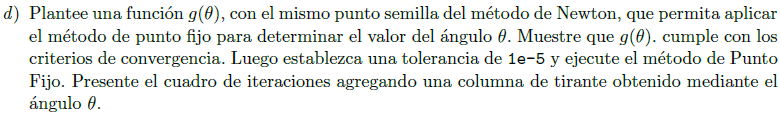

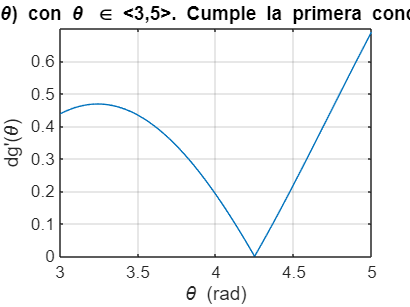

% presente aquí su resolución y aplique el método pedido y presente el
% cuadro de iteraciones

a = 3; b = 5; % segun el video podia abrir un poco el rango
tol = 1e-5;
theta = linspace(a, b, 1000);

g = @(theta) sin(theta) + ((8 * n * Q ./ (S^(1/2) * D^2)) .* ((4 .* theta) ./ D).^(2/3)).^(3/5);

% Primera condicion: |f'(x)| < 1 para todo x E <a,b>

syms x
dg = diff(g(x));
dg = matlabFunction(dg);

dg_values = abs(dg(theta));

plot(theta, dg_values);
xlabel('\theta (rad)');
ylabel("dg'(\theta)");
title('dg(\theta) con \theta \in <3,5>. Cumple la primera condicion');
grid on;

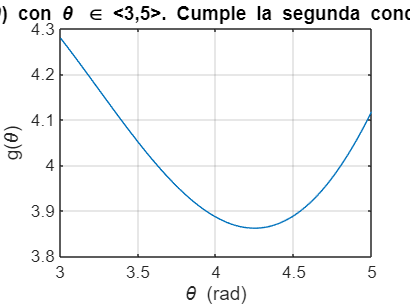


% Segunda condicion: Para todo x E [a,b], se cumple que g(x) E [a,b]

g_values = g(theta);
plot(theta, g_values);
xlabel('\theta (rad)');
ylabel("g(\theta)");
title('g(\theta) con \theta \in <3,5>. Cumple la segunda condicion');
grid on;


% Respuesta del metodo de punto fijo
% Ahora se usa 4 para el x0 como en los demas metodos ya que ya se comprobo
% que funciona para un rango mas amplio [3,5]
m3 = pfijo(g, 4, tol);  
m3 = [m3 tirante(m3)] 

m3 =    4.000000000000000   1.062110127410357
   3.886133842271400   1.022798576376781
   3.911976063984951   1.031802601441500
   3.905383921505191   1.029510157604520
   3.907026431842639   1.030081632141061
   3.906614655167836   1.029938381434386
   3.906717730303618   1.029974240786141
   3.906691918866569   1.029965261179179


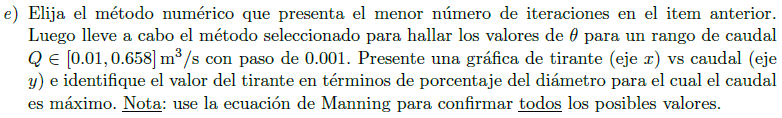

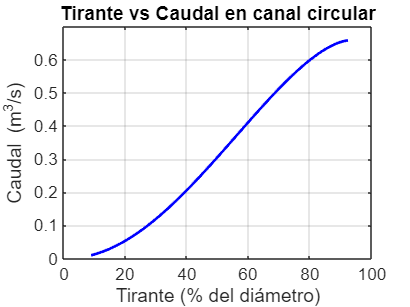

% Parámetros
n = 0.015;
D = 1.5;
S = 0.0001;
Q_values = 0.01:0.001:0.658;

% Vectores para los resultados
theta_values = zeros(size(Q_values));
tirante_values = zeros(size(Q_values));

% Se aplica newton a cada valor de Q_values
for i = 1:length(Q_values)
    Q = Q_values(i);
    f = @(theta) ((1 / n) * ((D^2 / 8) * (theta - sin(theta))) .* ...
        ((D ./ (4 * theta)) .* (theta - sin(theta))).^(2/3) * sqrt(S) - Q);
    
    res_newton = newton(f, 3, 1e-5);
    theta_values(i) = res_newton(end);
    tirante_values(i) = (D / 2) * (1 - cos(theta_values(i) / 2));
end

% Convertir tirante a porcentaje del diámetro
tirante_percentage = (tirante_values / D) * 100;

% Gráfica
plot(tirante_percentage, Q_values, 'b-', 'LineWidth', 1.5);
xlabel('Tirante (% del diámetro)');
ylabel('Caudal (m^3/s)');
title('Tirante vs Caudal en canal circular');
grid on;

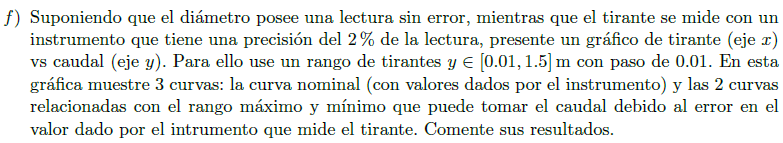

% muestre las gráficas y comente sus resultados

% muestre las gráficas y comente sus resultados

## Funciones:

% en esta sección van todas las funciones usadas
function z=biseccion2(f,a,b,Tol)
    c=(a+b)/2;
    error=(b-a)/2;
    z=[a c b f(a) f(c) f(b) error];
    N=ceil(log((b-a)/(2*Tol))/log(2));
    % fprintf('Se necesita %d iteraciones\n',N)
    while error>Tol
        if f(a)*f(c)<0
            b=c;
            else
            a=c;
        end
        c=(a+b)/2;
        error=(b-a)/2;
        % puse c entre a y b
        z=[z; a c b f(a) f(c) f(b) error];
    end
end

function z=newton(f,x0,Tol)
    syms x
    df=diff(f(x));
    dfu=matlabFunction(df);
    z=x0;
    error=1;
    while error>Tol
        x1=x0-f(x0)/dfu(x0);
        z=[z;x1];
        error=abs(x1-x0)/abs(x1);
        x0=x1;
    end
end

function z = pfijo(g,x0,tol)
    z=x0;
    error = 1;
    while error>tol
        x1=g(x0);
        z=[z;x1];
        error=abs(x1-x0)/abs(x1);
        x0=x1;
    end
end

